### **샤를의 법칙 (Charle's law)**

- **정의**: 기체에 열이 가해졌을 때 어떻게 팽창하는지를 설명하는 실험적 법칙.

- 압력이 일정할 때, 일정량의 기체의 부피(V)는 절대온도(T)에 비례.

- 수식: $\frac{V}{T} = C$ (여기서 $C$는 상수)

- 상태 1에서 상태 2로 변화할 때:

 
$$\frac{V_1}{T_1} = \frac{V_2}{T_2} = C$$


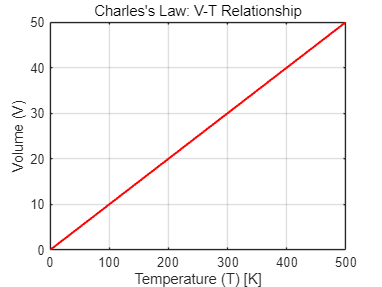

% 샤를의 법칙을 표현하기 위한 변수 설정
C = 0.1; % 상수 C (예: 0.1로 설정)

% 온도(T) 범위 설정
T = linspace(0, 500, 100); % 온도 0 ~ 500K까지 100개의 점으로 설정

% 부피(V) 계산 (샤를의 법칙: V = C * T)
V = C * T;

% 그래프 그리기
figure;
plot(T, V, 'r', 'LineWidth', 1.5); % V-T 그래프 (빨간색)

% 그래프 레이블 및 제목 설정
xlabel('Temperature (T) [K]');
ylabel('Volume (V)');
title('Charles''s Law: V-T Relationship');
grid on;

- **그래프**: 온도(T)와 부피(V) 간의 관계를 나타낸 그래프는 오른쪽 위로 올라가는 직선 형태입니다.

- 온도가 증가하면 부피도 증가하고, 온도가 감소하면 부피도 감소하는 관계입니다.

### **보일의 법칙 (Boyle's law)**

- **정의**: 온도가 일정할 때, 일정량의 기체의 압력(P)과 부피(V)는 서로 반비례 관계에 있음.

- 수식: $P \times V = C$(여기서 $C$는 상수)

- 상태 1에서 상태 2로 변화할 때: $P_1 V_1 = P_2 V_2 = C$

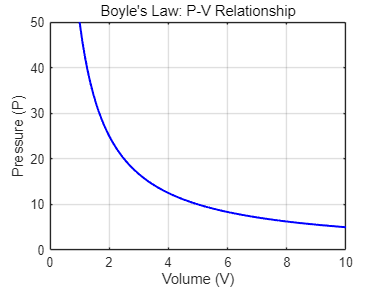

% 보일의 법칙을 표현하기 위한 변수 설정
C = 50; % 상수 C (예시로 50 설정)

% 부피(V) 범위 설정
V = linspace(1, 10, 100); % 부피 1 ~ 10까지 100개의 점으로 설정

% 압력(P) 계산 (보일의 법칙: P = C / V)
P = C ./ V;

% 그래프 그리기
figure;
plot(V, P, 'b', 'LineWidth', 1.5); % P-V 그래프 (파란색)

% 그래프 레이블 및 제목 설정
xlabel('Volume (V)');
ylabel('Pressure (P)');
title('Boyle''s Law: P-V Relationship');
grid on;

- **그래프**: 압력(P)과 부피(V) 간의 관계를 나타낸 그래프는 오른쪽으로 내려가는 곡선입니다.

- 압력이 증가하면 부피는 감소하고, 압력이 감소하면 부피는 증가하는 형태를 보입니다.

### **보일-샤를의 법칙 (Combined Gas Law)**

- **정의**: 압력(P), 부피(V), 온도(T)가 동시에 변화할 때 이상기체의 상태를 설명하는 법칙.

- 일정량의 기체가 차지하는 부피(V)와 압력(P)의 곱은 절대온도(T)에 비례.

- 수식: $\frac{PV}{T} = C$ (여기서 $C$는 상수)

**세부 관계식**

- 상태 1에서 상태 2로, 그리고 상태 3으로의 변화에서 이 관계식을 적용할 수 있습니다.

- 상태 1에서 상태 2: $\frac{P_1 V_1}{T_1} = \frac{P_2 V_2}{T_2} = C$

- 상태 2에서 상태 3: $\frac{P_2 V_2}{T_2} = \frac{P_3 V_3}{T_3} = C$

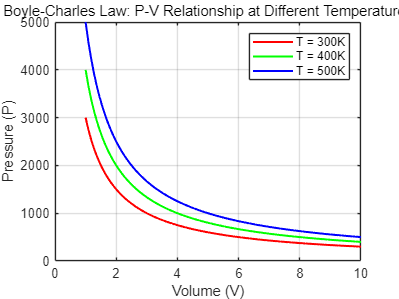

% 보일-샤를의 법칙을 표현하기 위한 변수 설정
T1 = 300; % 온도 1 (예: 300K)
T2 = 400; % 온도 2 (예: 400K)
T3 = 500; % 온도 3 (예: 500K)

% 부피(V) 범위 설정
V = linspace(1, 10, 100); % 부피 1 ~ 10까지 100개의 점으로 설정

% 상수 C 설정 (일반적으로 임의의 값, 여기서는 10으로 설정)
C = 10;

% 압력(P) 계산 (보일-샤를의 법칙: P = C*T / V)
P1 = C * T1 ./ V;
P2 = C * T2 ./ V;
P3 = C * T3 ./ V;

% 그래프 그리기
figure;
plot(V, P1, 'r', 'LineWidth', 1.5); % T1일 때 P-V 그래프 (빨간색)
hold on;
plot(V, P2, 'g', 'LineWidth', 1.5); % T2일 때 P-V 그래프 (초록색)
plot(V, P3, 'b', 'LineWidth', 1.5); % T3일 때 P-V 그래프 (파란색)

% 그래프 레이블 및 제목 설정
xlabel('Volume (V)');
ylabel('Pressure (P)');
title('Boyle-Charles Law: P-V Relationship at Different Temperatures');
legend('T = 300K', 'T = 400K', 'T = 500K', 'Location', 'northeast');
grid on;
hold off;

**그래프 설명**

- 그래프는 압력(P)과 부피(V) 간의 관계를 나타내며, 온도(T)에 따른 변화를 보여줍니다.

- 압력과 부피의 곱이 온도에 따라 변화하는 모습이 나타납니다.

- 세 가지 상태가 표시되어 있으며, 각 상태는 각각 다른 온도를 나타냅니다.

**이상기체 상태 변화의 해석**

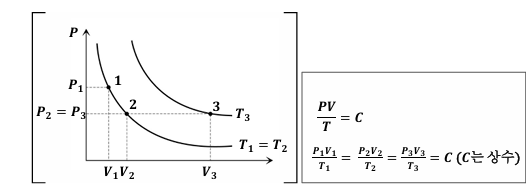

- **보일의 법칙 적용**: 등온과정에서 상태 1에서 상태 2로 변화

- 온도가 일정할 때, 압력과 부피가 반비례 관계를 가짐.

- **샤를의 법칙 적용**: 등압과정에서 상태 2에서 상태 3으로 변화

- 압력이 일정할 때, 부피는 온도에 비례하여 증가.

**문제**

- 압력: 720 kPa

- 초기 온도: 23°C (켈빈 단위로 변환하면 $23 + 273.15 = 296.2 \, K$)

- 초기 부피: $0.45 \, m^3$

- 부피가 2배로 팽창했을 때 (즉, $V_2 = 2 \times V_1 = 2 \times 0.45 = 0.9 \, m^3$)

- 변화 후의 기체의 온도($\degree C$)를 구하시오.

**해결**

샤를의 법칙에 따라 다음과 같이 계산할 수 있습니다.


$$\frac{V_1}{T_1} = \frac{V_2}{T_2}$$


이를 재정리하면,


$$T_2 = \frac{V_2}{V_1} \times T_1$$


주어진 값을 대입하면,


$$T_2 = 2 \times 296.2 = 592.4 \, K$$


이 값을 섭씨 온도로 변환하면,


$$T_2 - 273.15 = 319.2 \, \degree C$$


% 주어진 값
P = 720; % 압력 (kPa) - 압력은 일정하여 사용되지 않음
V1 = 0.45; % 초기 부피 (m^3)
V2 = 2 * V1; % 변화 후 부피 (2배 팽창)
T1_C = 23; % 초기 온도 (°C)
T1_K = T1_C + 273.15; % 초기 온도를 켈빈(K)으로 변환

% 샤를의 법칙을 이용하여 변화 후 온도 계산
T2_K = (V2 / V1) * T1_K; % 변화 후 온도 (K)
T2_C = T2_K - 273.15; % 켈빈을 섭씨로 변환

% 결과 출력
fprintf('변화 후의 기체의 온도는 %.2f°C입니다.\n', T2_C);

변화 후의 기체의 온도는 319.15°C입니다.


**문제**

- 초기 압력: $2.2 \, MPa$

- 초기 부피: $0.2 \, m^3$

- 압력이 초기 압력의 $\frac{1}{4}$�로 감소하였을 때, 기체가 차지하는 부피를 구하시오.

**해결**

보일의 법칙에 따르면 다음과 같이 표현할 수 있습니다.


$$P_1 V_1 = P_2 V_2$$


여기서,

- 
$$P_1 = 2.2 \, MPa$$


- 
$$V_1 = 0.2 \, m^3$$


- 
$$P_2 = \frac{1}{4} \times P_1 = \frac{1}{4} \times 2.2 = 0.55 \, MPa$$


위의 식을 재정리하여 $V_2$를 구하면,$V_2 = \frac{P_1}{P_2} \times V_1                  $


$$     V_2 = \frac{2.2}{0.55} \times 0.2 = 4 \times 0.2 = 0.8 \, m^3$$


따라서, 압력이 감소했을 때 기체가 차지하는 부피는 $0.8 \, m^3$입니다.

% 주어진 값
P1 = 2.2; % 초기 압력 (MPa)
V1 = 0.2; % 초기 부피 (m^3)
P2 = P1 / 4; % 압력이 초기의 1/4로 감소

% 보일의 법칙을 이용하여 변화 후 부피 계산
V2 = (P1 / P2) * V1;

% 결과 출력
fprintf('압력이 1/4로 감소했을 때 부피는 %.2f m^3입니다.\n', V2);

압력이 1/4로 감소했을 때 부피는 0.80 m^3입니다.


**이상기체 상태방정식**


$$P \bar{v} = R T$$


여기서

- $P
$: 절대압력 $(Pa)$

- $T$: 절대온도 $(K)$

- $\bar{v}$: 몰 비체적 (molar specific volume, $m^3/mol$)

- $R$: 일반기체상수 (universal gas constant), $8.314 \, J/(mol \cdot K)$

% 주어진 값
P = 101325; % 절대압력 (Pa, 대기압)
T = 298.15; % 절대온도 (K, 예: 25°C)
R = 8.314; % 일반기체상수 (J/(mol·K))

% 몰 비체적 계산 (이상기체 상태방정식: v_bar = RT / P)
v_bar = (R * T) / P;

% 결과 출력
fprintf('몰 비체적은 %.4f m^3/mol 입니다.\n', v_bar);

몰 비체적은 0.0245 m^3/mol 입니다.


**상태방정식의 변형**

- **몰 수 기준 상태방정식**:

- 기체의 몰 수를 $n$, 부피를 $V$라고 하면 몰 비체적은 $\bar{v} = \frac{V}{n}$입니다.

- 따라서 상태방정식은 다음과 같이 표현됩니다.


$$P \bar{v} = R T \quad \Rightarrow \quad P V = nRT$$


- 여기서 $R$은 일반기체상수입니다.

- **질량 기준 상태방정식**:

- 질량 $m
$으로 상태방정식을 나타내면$n = \frac{m}{M}$�이 됩니다. (여기서 $M$은 분자량)

- 따라서 식은 다음과 같이 변형됩니다.


$$PV = \frac{m}{M} RT \quad \Rightarrow \quad PV = m \hat{R} T$$


- 이때, $\hat{R}$은 특정 기체에 대한 기체상수로서 $\hat{R} = \frac{R}{M}$입니다.

- **비체적과 밀도 기준 상태방정식**:

- 비체적$v = \frac{V}{m}$이며, 밀도 $\rho = \frac{1}{v}$�입니다.

- 이를 이용하면 상태방정식은 다음과 같이 표현됩니다. 


$$P v = \hat{R} T \quad \text{또는} \quad P = \rho \hat{R} T$$


1. $ PV = nRT$ 형태(**몰 수 기준 상태방정식)**

% 주어진 값
n = 2; % 몰 수 (mol)
R = 8.314; % 일반기체상수 (J/(mol·K))
T = 298.15; % 절대온도 (K)
V = 0.05; % 부피 (m^3)

% 이상기체 상태방정식
P = (n * R * T) / V;

% 결과 출력
fprintf('압력은 %.2f Pa입니다.\n', P);

압력은 99152.76 Pa입니다.


2. $PV = mRT$ 형태**(질량 기준 상태방정식)**

% 주어진 값
m = 5; % 질량 (kg)
M = 0.02896; % 공기의 분자량 (kg/mol)
R = 8.314; % 일반기체상수 (J/(mol·K))
T = 298.15; % 절대온도 (K)
V = 1; % 부피 (m^3)

% 기체상수 R_hat 계산
R_hat = R / M;

% 상태방정식
P = (m * R_hat * T) / V;

% 결과 출력
fprintf('압력은 %.2f Pa입니다.\n', P);

압력은 427972.91 Pa입니다.


3. $P = \rho RT$ 형태**(밀도 기준 상태방정식)**

% 주어진 값
rho = 1.225; % 밀도 (kg/m^3)
M = 0.02896; % 공기의 분자량 (kg/mol)
R = 8.314; % 일반기체상수 (J/(mol·K))
T = 298.15; % 절대온도 (K)

% 기체상수 R_hat 계산
R_hat = R / M;

% 상태방정식
P = rho * R_hat * T;

% 결과 출력
fprintf('압력은 %.2f Pa입니다.\n', P);

압력은 104853.36 Pa입니다.


**정적비열 (**$C_v$**)**

- **정의**: 부피를 일정하게 유지하면서 단위 질량의 물질의 온도를 1도 올리는데 필요한 열량.

- 수식으로 표현하면: 


$$C_v = \frac{1}{m} \left(\frac{\delta q}{\delta T}\right)_v = \frac{1}{m} \left(\frac{\partial U}{\partial T}\right)_v = \left(\frac{\partial u}{\partial T}\right)_v$$


- 여기서:

- $C_v$: 정적비열 ($J/kg\cdot K$ 또는 $kJ/kmol\cdot K$)

- $m$: 질량 ($kg$)

- $q$: 가해진 열량 ($J$)

- $U$: 내부에너지 ($J$)

- $u = \frac{U}{m}$: 단위 질량당 내부에너지 ($J/kg$)

- $T$: 절대온도 ($K$)

**열역학 제1법칙을 통한 해석**

- 열역학 제1법칙은 다음과 같이 주어집니다. $\delta q = dU + PdV$

- 부피가 일정할 경우 ($dV = 0$), 위 식은 다음과 같이 단순화됩니다. $\delta q = dU$

- 이 의미는 정적 과정에서는 외부에 대한 일의 성분이 없으므로, 공급된 열량 $\delta q$가 전적으로 내부에너지 증가 $dU$에만 사용된다는 것입니다.

**정적비열의 물리적 의미**

- $C_v$는 부피가 일정한 상황에서 온도를 1도 올리기 위해 기체 또는 물질에 가해지는 열량입니다.

- 내부에너지의 증가는 직접적으로 온도 변화에 관련되며, 이 과정에서는 부피 변화가 없기 때문에 외부에 대한 일의 변화도 발생하지 않습니다.

**예시로 이해하기**

만약 $m = 2 \, kg$의 물질이 있고, 그 물질의$C_v = 0.7 \, kJ/(kg \cdot K)$일 때, 온도를 $5K$ 올리는데 필요한 열량을 계산해 보겠습니다.


$$Q = m \times C_v \times \Delta T = 2 \times 0.7 \times 5 = 7 \, kJ$$


즉, 이 물질을 $5K$만큼 올리기 위해서는 $7kJ$의 열이 필요하다는 것을 알 수 있습니다.

**정압비열 (**$C_p$**)**

- **정의**: 압력을 일정하게 유지하면서 단위 질량의 물질의 온도를 1도 올리는데 필요한 열량.

- 수식으로 표현하면: 

$C_p = \frac{1}{m} \left(\frac{\delta q}{\delta T}\right)_p = \frac{1}{m} \left(\frac{\partial H}{\partial T}\right)_p = \left(\frac{\partial h}{\partial T}\right)_p$�

- 여기서:

- $C_p$: 정압비열 ($J/kg\cdot K$ 또는 $kJ/kmol\cdot K$)

- $m$: 질량 ($kg$)

- $q$: 가해진 열량 ($J$)

- $H$: 엔탈피 ($J$)

- $h = \frac{H}{m}$: 단위 질량당 엔탈피 ($J/kg$)

- $T$: 절대온도 ($K$)

**열역학적 해석: 열역학 제1법칙과 정압비열**

- 열역학 제1법칙을 에너지 보존의 법칙으로 나타내면 다음과 같습니다: 


$$\delta q = dH - VdP$$


- 압력이 일정한 경우$ (dP = 0)$, 위 식은 다음과 같이 단순화됩니다. $\delta q = dH$

- 이는 압력이 일정할 때 공급된 열량 $\delta q$가 전적으로 엔탈피 증가$dH$에 사용된다는 것을 의미합니다.

**정압비열의 물리적 의미**

- $C_p$는 압력이 일정한 상황에서 온도를 1도 올리기 위해 기체 또는 물질에 가해지는 열량입니다.

- 이 과정에서는 부피가 변화할 수 있기 때문에 외부에 대해 일(work)이 발생할 수 있습니다. 따라서 $C_p$는 정적비열 $C_v$보다 일반적으로 더 큰 값을 갖습니다.

**정적비열 **$C_v$**와 정압비열 **$C_p$**의 관계**

이상기체의 경우 다음과 같은 관계식이 성립합니다.


$$C_p = C_v + R$$


- 여기서 $R$은 기체상수입니다.

- 이 관계는 압력이 일정할 때 외부에 대한 일의 성분이 추가되기 때문에 $C_p$가 $C_v$보다 크다는 것을 나타냅니다.

**예시를 통한 이해**

만약 $m = 3 \, kg$의 물질이 있고, 그 물질의$C_p = 1.0 \, kJ/(kg \cdot K)$일 때, 온도를 $10K$ 올리는데 필요한 열량을 계산해보겠습니다.


$$Q = m \times C_p \times \Delta T = 3 \times 1.0 \times 10 = 30 \, kJ$$


즉, 이 물질을 $10K$만큼 온도를 높이기 위해서는 $30kJ$의 열이 필요합니다.

**비압축성(incompressible) 물질의 특성**

- **비압축성 물질**: 비체적 또는 밀도가 일정한 물질로, 일반적으로 액체와 고체를 의미합니다.

- 이러한 물질의 경우 압력 변화에 따른 부피 변화가 거의 없기 때문에 비체적을 일정하다고 가정할 수 있습니다.

**정적비열과 정압비열의 관계**

- 비압축성 물질의 경우, 정적비열($C_v$)과 정압비열($C_p$)이 동일합니다.

- 따라서 $C_v = C_p = C$로 표현됩니다.

**엔탈피와 내부 에너지의 관계**

- 엔탈피의 정의:$h = u + Pv$이 식을 미분하면 다음과 같습니다:


$$dh = du + Pdv + v dP$$


- 비압축성 물질의 경우, 다음과 같은 특성이 있습니다:

- 부피가 일정하므로 $dv = 0$.

- 고체나 액체의 비체적 $v$는 매우 작으므로 $v dP$ 항 역시 무시할 수 있습니다.

따라서:

- 
$$dh \approx du$$


- 정적과정 및 정압과정에서 동일한 결과를 얻으며, $C_v$와 $C_p$는 차이 없이 $C$로 나타낼 수 있습니다.

**수식으로 표현**

- 내부 에너지 변화: $du = C_v dT = C dT$

- 엔탈피 변화: $dh = C_p dT = C dT$

- 따라서, 비압축성 물질에서는 $C_v = C_p = C$가 성립합니다.

**내부 에너지와 엔탈피의 정의**

- 이상기체의 내부 에너지 $u$와 엔탈피 $h$는 온도에만 의존합니다.

- 이를 기반으로 각각의 비열과의 관계를 수식으로 나타낼 수 있습니다.

**2. 비열과의 관계**

- **정적비열 **$C_v$: 부피가 일정한 상태에서의 온도 변화에 따른 내부 에너지의 변화율. 


$$C_v = \left(\frac{du}{dT}\right)$$


- **정압비열 **$C_p$: 압력이 일정한 상태에서의 온도 변화에 따른 엔탈피의 변화율. 


$$C_p = \left(\frac{dh}{dT}\right)$$


**3. 내부 에너지와 엔탈피의 변화**

- 온도 $T$에 따른 내부 에너지와 엔탈피의 변화는 다음과 같이 표현됩니다: 


$$du = C_v dT               $$



$$    dh = C_p dT$$


- 질량 $m$을 고려하면, 전체 내부 에너지 $U$와 엔탈피 $H$의 변화는 다음과 같습니다: 


$$dU = m C_v dT              $$



$$    dH = m C_p dT$$


- 이상기체의 경우 내부 에너지와 엔탈피는 온도에만 의존하기 때문에 $C_v$와 $C_p$는 각각 내부 에너지와 엔탈피의 온도에 대한 변화율을 나타냅니다.

- 실제로 내부 에너지나 엔탈피의 총량을 계산할 때는 주어진 온도 변화에 정적비열 $C_v$또는 정압비열 $C_p$를 곱하는 것으로 구할 수 있습니다.

**내부 에너지와 엔탈피의 총 변화량**

**1. 내부 에너지의 변화 (**$\Delta U$**)**

- 이상기체의 온도가 $T_1$에서 $T_2$로 변화할 때, 내부 에너지의 변화는 다음과 같이 표현됩니다.


$$\Delta U = m C_v (T_2 - T_1)$$


- $m$: 질량 ($kg$)

- $C_v$: 정적비열 ($J/kg\cdot K$)

- $T_1, T_2$: 초기와 최종 온도 ($K$)

- 이는 $u = u(T)$로 온도에만 의존하는 이상기체의 특성을 반영한 결과입니다.

**2. 엔탈피의 변화 (**$\Delta H$**)**

- 이상기체의 엔탈피 변화는 다음과 같이 주어집니다.


$$\Delta H = m C_p (T_2 - T_1)$$


- $C_p$: 정압비열 ($J/kg\cdot K$)

- 엔탈피는 $h = u + Pv$의 관계에서 온도에만 의존하며, 따라서 $h = h(T)$로 나타낼 수 있습니다.

**이상기체의 상태방정식**

- 이상기체 방정식은 $Pv = RT$로 표현되며, 내부 에너지와 엔탈피는 각각 다음과 같은 형태를 가집니다.

- 내부 에너지: $u = u(T)$

- 엔탈피: $h = u(T) + RT$

- **순수 물질의 내부 에너지**는 주로 온도 $T$에 의해 결정되며, 압력 $P$나 비체적$ v$등의 상태 변수에는 영향을 받지 않습니다.

- 이는 이상기체의 경우 내부 에너지가 오직 온도의 함수로만 결정된다는 이상적 모델을 잘 나타내며, 현실에서의 실제 가스도 이러한 경향을 많이 따릅니다.

**비열비**

**1. 정적비열과 정압비열의 기본 정의**

- $C_v = \frac{du}{dT}$ : 정적비열 (부피가 일정할 때 내부 에너지의 온도 변화율)

- $C_p = \frac{dh}{dT}$� : 정압비열 (압력이 일정할 때 엔탈피의 온도 변화율)

**2. 이상기체의 상태방정식과 미분**

- 상태방정식: $Pv = RT$

- 양변을 미분하면: $Pdv + v dP = RdT$

- 압력이 일정할 때 ($dP = 0$), $Pdv = RdT$가 성립합니다.

**3. 에너지식과 정압비열, 정적비열의 관계**

- 에너지식: $\delta q = du + \delta w = du + Pdv$

- 여기에 위에서 유도한 $Pdv = RdT$를 대입하면, 


$$C_p dT = C_v dT + R dT$$
  

- 따라서, 


$$C_p = C_v + R$$


**4. 정압비열과 정적비열의 관계**

- 이상기체의 경우, 정압비열과 정적비열의 차이는 기체상수 $R
$로 표현됩니다: $C_p - C_v = R$

**5. 비열비 (**$k$**)**

- **정의**: 두 비열의 비율을 비열비 $k$로 정의합니다. $k = \frac{C_p}{C_v}$��

- 비열비 $ k$를 이용하면, $C_p = k C_v$�

**6. **$C_v$**�****와 **$C_p$**�****를 비열비를 통해 표현**

- 위의 관계식$C_p - C_v = R$와 $C_p = k C_v$�를 이용하면: 


$$C_v = \frac{1}{k - 1} R     $$



$$  C_p = \frac{k}{k - 1} $$


**7. 주요 특성**

- 기체상수 $R$은 항상 양수이므로 $C_p > C_v$�가 항상 성립.

- 따라서 비열비 $k = \frac{C_p}{C_v}$는 언제나 1보다 큰 값을 가집니다.

**문제**

**1. 주어진 조건**

- 질량 $m = 10 \, \text{kg}$

- 가해진 열량 $Q = 1200 \, \text{kJ}$

- 초기 온도 $T_1 = 25 + 273.15 = 298.15 \, \text{K}$

- 기체의 비열비 $k = 1.4$

- 기체상수 $R = 0.35 \, \text{kJ}/(kg \cdot K)$

**2. 정압비열과 정적비열 계산**

정압비열 $C_p$�와 정적비열 $C_v$�는 다음과 같이 계산됩니다.


$$C_p = \frac{k}{k - 1} R
$$



$$C_p = \frac{1.4}{1.4 - 1} \times 0.35 = \frac{1.4}{0.4} \times 0.35 = 1.225 \, \text{kJ}/(kg \cdot K)                      $$



$$C_v = \frac{1}{0.4} \times 0.35 = 0.875 \, \text{kJ}/(kg \cdot K)$$


**3. 최종 온도 계산**

가해진 열량 $Q$를 이용하여 최종 온도$T_2$를 계산합니다.


$$Q = m C_p (T_2 - T_1)$$


따라서,


$$T_2 = \frac{Q}{m C_p} + T_1             $$



$$T_2 = \frac{1200}{10 \times 1.225} + 298.15                     $$



$$  T_2 = \frac{1200}{12.25} + 298.15                    $$



$$T_2 = 97.96 + 298.15 = 396.11 \, \text{K}$$


이를 섭씨로 변환하면


$$T_2 - 273.15 = 122.96 \, \text{\degree C}$$


**4. 내부 에너지 변화 계산**

내부 에너지 변화 $\Delta U$는 다음과 같이 계산됩니다.


$$\Delta U = m C_v (T_2 - T_1)             $$



$$\Delta U = 10 \times 0.875 \times (396.11 - 298.15) 
               $$



$$\Delta U = 10 \times 0.875 \times 97.96             $$



$$\Delta U = 857.14 \, \text{kJ}$$


**최종 결과**

- **최종 온도 **$T_2$**�**: $396.11 K$ 또는 $122.96\degree C$

- **내부 에너지 변화량 **$\Delta U: 857.14 kJ$

% 주어진 데이터
m = 10;               % 질량 (kg)
Q = 1200;             % 가해진 열량 (kJ)
T1 = 25 + 273.15;     % 초기 온도 (K) (섭씨를 켈빈으로 변환)
k = 1.4;              % 기체의 비열비
R = 0.35;             % 기체상수 (kJ/kg·K)

% 정압비열과 정적비열 계산
Cp = (k / (k - 1)) * R;   % 정압비열 (kJ/kg·K)
Cv = (1 / (k - 1)) * R;   % 정적비열 (kJ/kg·K)

% 최종 온도 계산
T2 = (Q / (m * Cp)) + T1;  % 최종 온도 (K)
T2_Celsius = T2 - 273.15;  % 최종 온도 (°C)

% 내부 에너지 변화 계산
delta_U = m * Cv * (T2 - T1); % 내부 에너지 변화량 (kJ)

% 엔탈피 변화 계산
delta_H = m * Cp * (T2 - T1); % 엔탈피 변화량 (kJ)

% 결과 출력
fprintf('최종 온도 T2: %.2f K (%.2f °C)\n', T2, T2_Celsius);

최종 온도 T2: 396.11 K (122.96 °C)


fprintf('내부 에너지 변화 ΔU: %.2f kJ\n', delta_U);

내부 에너지 변화 ΔU: 857.14 kJ


fprintf('엔탈피 변화 ΔH: %.2f kJ\n', delta_H);

엔탈피 변화 ΔH: 1200.00 kJ


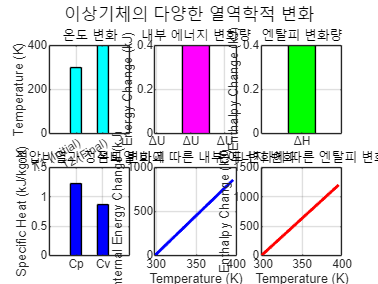


% 시각화
figure;

% 그래프 1: 초기 및 최종 온도 변화
subplot(2, 3, 1); % 2행 3열의 서브플롯 중 첫 번째
bar([T1, T2], 0.4, 'FaceColor', 'c'); % 막대그래프 그리기
set(gca, 'XTickLabel', {'T1 (Initial)', 'T2 (Final)'}); % x축 레이블
ylabel('Temperature (K)'); % y축 레이블
title('온도 변화'); % 그래프 제목
grid on;

% 그래프 2: 내부 에너지 변화량
subplot(2, 3, 2); % 2행 3열의 서브플롯 중 두 번째
bar(delta_U, 0.4, 'FaceColor', 'm'); % 막대그래프 그리기
set(gca, 'XTickLabel', {'ΔU'}); % x축 레이블
ylabel('Energy Change (kJ)'); % y축 레이블
title('내부 에너지 변화량'); % 그래프 제목
grid on;

% 그래프 3: 엔탈피 변화량
subplot(2, 3, 3); % 2행 3열의 서브플롯 중 세 번째
bar(delta_H, 0.4, 'FaceColor', 'g'); % 막대그래프 그리기
set(gca, 'XTickLabel', {'ΔH'}); % x축 레이블
ylabel('Enthalpy Change (kJ)'); % y축 레이블
title('엔탈피 변화량'); % 그래프 제목
grid on;

% 그래프 4: 정압비열과 정적비열 비교
subplot(2, 3, 4); % 2행 3열의 서브플롯 중 네 번째
bar([Cp, Cv], 0.4, 'FaceColor', 'b'); % 막대그래프 그리기
set(gca, 'XTickLabel', {'Cp', 'Cv'}); % x축 레이블
ylabel('Specific Heat (kJ/kg·K)'); % y축 레이블
title('정압비열과 정적비열 비교'); % 그래프 제목
grid on;

% 그래프 5: 온도 변화에 따른 내부 에너지 변화
subplot(2, 3, 5); % 2행 3열의 서브플롯 중 다섯 번째
T_values = linspace(T1, T2, 100); % 온도 변화 범위
U_values = m * Cv * (T_values - T1); % 내부 에너지 변화 계산
plot(T_values, U_values, 'b', 'LineWidth', 2);
xlabel('Temperature (K)'); % x축 레이블
ylabel('Internal Energy Change (kJ)'); % y축 레이블
title('온도 변화에 따른 내부 에너지 변화'); % 그래프 제목
grid on;

% 그래프 6: 온도 변화에 따른 엔탈피 변화
subplot(2, 3, 6); % 2행 3열의 서브플롯 중 여섯 번째
H_values = m * Cp * (T_values - T1); % 엔탈피 변화 계산
plot(T_values, H_values, 'r', 'LineWidth', 2);
xlabel('Temperature (K)'); % x축 레이블
ylabel('Enthalpy Change (kJ)'); % y축 레이블
title('온도 변화에 따른 엔탈피 변화'); % 그래프 제목
grid on;

% 전체 그래프 설정
sgtitle('이상기체의 다양한 열역학적 변화');

- **첫 번째 그래프**: 정압비열 $C_p$과 정적비열 $C_v$�의 비교 막대그래프.

- **두 번째 그래프**: 내부 에너지 변화량 $\Delta U$를 나타내는 막대그래프.

- **세 번째 그래프**: 온도 변화에 따른 내부 에너지의 변화 그래프. 온도가 증가함에 따라 내부 에너지 변화량이 어떻게 달라지는지 보여줌.

- **네 번째 그래프**: 온도 변화에 따른 엔탈피의 변화 그래프. 온도 변화에 따라 엔탈피가 어떻게 변하는지 보여줌.

**문제**

- **주어진 조건**:

- 질량 $m = 3 \, \text{kg}$

- 초기 압력 $P_1 = 101 \, \text{kPa}$

- 초기 부피 $V_1 = 3.2 \, \text{m}^3$

- 기체상수 $R = 266 \, \text{J}/(kg \cdot K)$

- 최종 온도 $T_2 = 188 + 273.15 = 461.15 \, \text{K}$

**1. 이상기체 상태방정식으로 초기 온도 **$T_1$**�**** 계산**

이상기체 상태방정식은 다음과 같습니다:

$P_1 V_1 = m R T_1$�

$T_1$�을 구하기 위해 식을 정리하면,

$T_1 = \frac{P_1 V_1}{m R}$��

주어진 값을 대입하면,


$$T_1 = \frac{101 \times 10^3 \times 3.2}{3 \times 266}   
           $$



$$T_1 = \frac{323200}{798} \approx 405.01 \, \text{K}$$


**2. 온도 변화량**$\Delta T$** 계산**


$$\Delta T = T_2 - T_1                   $$



$$\Delta T = 461.15 - 405.01              $$



$$\Delta T = 56.14 \, \text{K} \approx 56.2 \, \text{\degree C}$$


**최종 결과**

- **온도 변화량**: $56.2\degree C$

% 주어진 데이터
m = 3;                   % 질량 (kg)
P1 = 101 * 10^3;         % 초기 압력 (Pa) = 101 kPa
V1 = 3.2;                % 초기 부피 (m^3)
R = 266;                 % 기체상수 (J/kg·K)
T2_Celsius = 188;        % 최종 온도 (°C)

% 초기 온도 계산
T1 = (P1 * V1) / (m * R); % 초기 온도 (K)

% 최종 온도를 켈빈 단위로 변환
T2 = T2_Celsius + 273.15; % 최종 온도 (K)

% 온도 변화량 계산
delta_T = T2 - T1;        % 온도 변화량 (K 또는 °C)

% 정압비열과 정적비열 계산
Cp = (1.4 / (1.4 - 1)) * R / 1000;  % 정압비열 (kJ/kg·K)
Cv = (1 / (1.4 - 1)) * R / 1000;    % 정적비열 (kJ/kg·K)

% 내부 에너지 변화량 계산
delta_U = m * Cv * delta_T; % 내부 에너지 변화량 (kJ)

% 결과 출력
fprintf('초기 온도 T1: %.2f K\n', T1);

초기 온도 T1: 405.01 K


fprintf('최종 온도 T2: %.2f K (%.2f °C)\n', T2, T2_Celsius);

최종 온도 T2: 461.15 K (188.00 °C)


fprintf('온도 변화량 ΔT: %.2f K 또는 %.2f °C\n', delta_T, delta_T);

온도 변화량 ΔT: 56.14 K 또는 56.14 °C


fprintf('내부 에너지 변화량 ΔU: %.2f kJ\n', delta_U);

내부 에너지 변화량 ΔU: 111.99 kJ


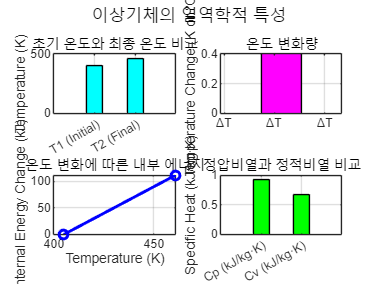


% 시각화
figure;

% 그래프 1: 초기 온도와 최종 온도 비교
subplot(2, 2, 1); % 2행 2열의 서브플롯 중 첫 번째
bar([T1, T2], 0.4, 'FaceColor', 'c'); % 막대그래프 그리기
set(gca, 'XTickLabel', {'T1 (Initial)', 'T2 (Final)'}); % x축 레이블
ylabel('Temperature (K)'); % y축 레이블
title('초기 온도와 최종 온도 비교'); % 그래프 제목
grid on;

% 그래프 2: 온도 변화량
subplot(2, 2, 2); % 2행 2열의 서브플롯 중 두 번째
bar(delta_T, 0.4, 'FaceColor', 'm'); % 막대그래프 그리기
set(gca, 'XTickLabel', {'ΔT'}); % x축 레이블
ylabel('Temperature Change (K or °C)'); % y축 레이블
title('온도 변화량'); % 그래프 제목
grid on;

% 그래프 3: 내부 에너지 변화
subplot(2, 2, 3); % 2행 2열의 서브플롯 중 세 번째
plot([T1, T2], [0, delta_U], 'b-o', 'LineWidth', 2); % 온도에 따른 내부 에너지 변화
xlabel('Temperature (K)'); % x축 레이블
ylabel('Internal Energy Change (kJ)'); % y축 레이블
title('온도 변화에 따른 내부 에너지'); % 그래프 제목
grid on;

% 그래프 4: Cp와 Cv 비교
subplot(2, 2, 4); % 2행 2열의 서브플롯 중 네 번째
bar([Cp, Cv], 0.4, 'FaceColor', 'g'); % 막대그래프 그리기
set(gca, 'XTickLabel', {'Cp (kJ/kg·K)', 'Cv (kJ/kg·K)'}); % x축 레이블
ylabel('Specific Heat (kJ/kg·K)'); % y축 레이블
title('정압비열과 정적비열 비교'); % 그래프 제목
grid on;

% 전체 그래프 설정
sgtitle('이상기체의 열역학적 특성'); 

**보일-샤를의 법칙**

보일-샤를의 법칙은 압력, 부피, 온도의 관계를 나타내는 이상기체 법칙으로 다음과 같이 표현됩니다:

$\frac{P_1 V_1}{T_1} = \frac{P_2 V_2}{T_2}$��

여기서 주행 전후 타이어의 부피는 변하지 않는다고 가정할 수 있기 때문에 $V_1 = V_2$가 되어 식을 단순화할 수 있습니다.

**간단화된 식**

$\frac{P_1}{T_1} = \frac{P_2}{T_2}$��

이 식을 사용하여 최종 온도$T_2$�를 구해보겠습니다.

**주어진 조건**

- 주행 전 타이어 공기의 압력 


$$P_1 = 99 \, \text{kPa} + 250 \, \text{kPa} = 349 \, \text{kPa} $$


- 주행 후 타이어 공기의 압력 


$$P_2 = 99 \, \text{kPa} + 263 \, \text{kPa} = 362 \, \text{kPa}$$


- 주행 전 타이어 공기의 온도 


$$T_1 = 25 \, \text{\degree C} = 25 + 273.15 = 298.15 \, \text{K}$$


**최종 온도 계산**


$$T_2 = \frac{P_2}{P_1} \times T_1           $$



$$T_2 = \frac{362}{349} \times 298.15          $$



$$T_2 \approx 309.3 \, \text{K}$$


이를 섭씨 온도로 변환하면:


$$T_2 - 273.15 \approx 309.3 - 273.15 = 36.15 \, \text{\degree C}$$


**온도 상승량**


$$\Delta T = T_2 - T_1 $$



$$\Delta T = 36.15 - 25 = 11.15 \, \text{\degree C}$$


**결론**

- 주행 후 타이어 공기의 온도는 약 **36.15°C**이며, 온도 상승량은 약 **11.15°C**입니다.

% 주어진 데이터
P1 = 99 + 250;              % 주행 전 타이어 공기 압력 (kPa)
P2 = 99 + 263;              % 주행 후 타이어 공기 압력 (kPa)
T1_Celsius = 25;       % 주행 전 타이어 공기 온도 (°C)

% 주행 전 온도를 켈빈 단위로 변환
T1 = T1_Celsius + 273.15; % (K)

% 보일-샤를의 법칙에 따른 최종 온도 계산
T2 = (P2 / P1) * T1;   % 최종 온도 (K)
T2_Celsius = T2 - 273.15; % 최종 온도 (°C)

% 온도 변화량 계산
delta_T = T2_Celsius - T1_Celsius;

% 결과 출력
fprintf('최종 온도 T2: %.2f °C\n', T2_Celsius);

최종 온도 T2: 36.11 °C


fprintf('온도 변화량 ΔT: %.2f °C\n', delta_T);

온도 변화량 ΔT: 11.11 °C


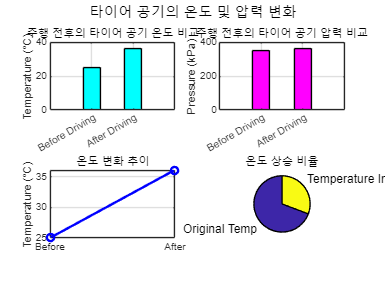


% 시각화
figure;

% 그래프 1: 주행 전후 온도 비교 (막대그래프)
subplot(2, 2, 1); % 2행 2열의 서브플롯 중 첫 번째
bar([T1_Celsius, T2_Celsius], 0.4, 'FaceColor', 'c'); % 막대그래프 그리기
set(gca, 'XTickLabel', {'Before Driving', 'After Driving'}); % x축 레이블
ylabel('Temperature (°C)'); % y축 레이블
title('주행 전후의 타이어 공기 온도 비교'); % 그래프 제목
grid on;

% 그래프 2: 압력 비교 (막대그래프)
subplot(2, 2, 2); % 2행 2열의 서브플롯 중 두 번째
bar([P1, P2], 0.4, 'FaceColor', 'm'); % 막대그래프 그리기
set(gca, 'XTickLabel', {'Before Driving', 'After Driving'}); % x축 레이블
ylabel('Pressure (kPa)'); % y축 레이블
title('주행 전후의 타이어 공기 압력 비교'); % 그래프 제목
grid on;

% 그래프 3: 주행 전후의 온도 변화 (선 그래프)
subplot(2, 2, 3); % 2행 2열의 서브플롯 중 세 번째
plot([0, 1], [T1_Celsius, T2_Celsius], 'b-o', 'LineWidth', 2); % 선 그래프 그리기
set(gca, 'XTick', [0, 1], 'XTickLabel', {'Before', 'After'}); % x축 레이블
ylabel('Temperature (°C)'); % y축 레이블
title('온도 변화 추이'); % 그래프 제목
grid on;

% 그래프 4: 온도 상승 비율 (원형 차트)
subplot(2, 2, 4); % 2행 2열의 서브플롯 중 네 번째
pie([T1_Celsius, delta_T], {'Original Temp', 'Temperature Increase'}); % 원형 차트 그리기
title('온도 상승 비율'); % 그래프 제목

% 전체 그래프 설정
sgtitle('타이어 공기의 온도 및 압력 변화');